**此函数计算激发表面等离激元所需要的角度**

**输入参数说明：**

lambda0：入射光波长

n0：棱镜折射率

epsilonm：金属的介电常数

**原理分析：**

如图是激发表面等离激元的 Kretschmann 结构，尝试计算其激发角度 $\theta_{sp}$

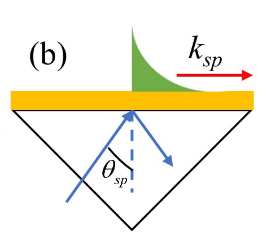

利用高折射率介质（$n_0$为介质的折射率，$n_0 = \sqrt{\epsilon_2}>1$ ）可以增大激发光波矢，当满足波矢匹配条件时，SPPs在金属/空气界面被激发，可得


$$Re[k_{SPPs}] = Re[{\sqrt{\epsilon_1\epsilon_m/(\epsilon_1+\epsilon_m)}\omega_0/c]=Re[\sqrt{\epsilon_2}sin\theta_{sp}]\omega_0/c$$


式中$\epsilon_m$为金属的介电常数，$\omega_0$ 为真空中的角频率，$\theta_{sp}$为表面等离激元的共振激发角。

function angle = caculate_spp_angle(lambda0, n0, epsilonm)

if nargin < 3  % 判断输入的参数是否小于3个，是则为参数赋予默认值，不是则为参数赋予输入值
    lambda0 = 632.8e-9; % 入射光波长（米）
    n0 = 1.515; % 棱镜折射率，默认1.515
    epsilonm = -17.2355+0.4982i; % 金属银的介电常数
end

c = 3e8; % 真空光速
nu = c/lambda0; % 光频率 
omega0 = 2*pi*nu; % 真空角频率
% k0 = 2*pi/lambda0; % 入射光波矢
epsilon1 = 1;
Kspps = sqrt(epsilon1*epsilonm/(epsilon1+epsilonm))*omega0/c;
theta_sp = asin(real(Kspps)*c/omega0/n0);
angle = 180*theta_sp/pi;
end